# Team 3: Hexapod Robot Max Joint Angle Rigid Body Tree Robot Model

#### Gary Encinas, Justin Fossum, Jason Munger, and Mithulesh Ramkumar

## Building The Model

This code was derived and adjusted from our group script called "Hexapod_Robot_Leg_Dynamics.mlx" in which we built the first rigid body system.

### Environment Setup

First, we should remove items from workspace, freeing up system memory, and clear current command window.

clf('reset'); %Clear current figure window
clear; % Remove items from workspace, freeing up system memory
clc; % Clear current command window

### Initializing the Estimated Max Joint Angles

These joint angles are based on our current understanding of the joint angles as seen within our SolidWorks model. This code will build the rigid body tree model and then itterate through all possible joint angles to determine the actual maximum joint angles. This determination will be based on the largest possible set of data that can be bounded without self collisions.

hip_joint_range_d = [linspace(-45,-35,11), linspace(35,45,11)]; % Hip joint angles in degrees -45 to +45
knee_joint_range_d = [linspace(-38,-28,11), linspace(92,102,11)]; % Knee joint min+10 and max-10 angles in degrees -38 to +102
ankle_joint_range_d = [linspace(-135,-125,11), linspace(-10,0,11)]; % Ankle joint min+10 and max-10 angles in degrees-135 to 0

hip_joint_range_r = deg2rad(hip_joint_range_d); % Hip joint angles in radians
knee_joint_range_r = deg2rad(knee_joint_range_d); % Knee joint angles in radians
ankle_joint_range_r = deg2rad(ankle_joint_range_d); % Ankle joint angles in radians

collision_map = zeros(length(hip_joint_range_r),length(knee_joint_range_r),length(ankle_joint_range_r));
collision_angles = zeros(length(hip_joint_range_r)*length(knee_joint_range_r)*length(ankle_joint_range_r),3);
counter = 0;

### Building the Rigid Tree Model

When building this model, the leg length visuals and collision meshes are reused, so rather than the full string path every time, we have listed them all as variables in the beginning. Keeping true with that fashion, the DH parameters are only changed by a ratio of $\frac{\pi }{3}$ each new leg so there is a count variable that can be called to index the leg creations.

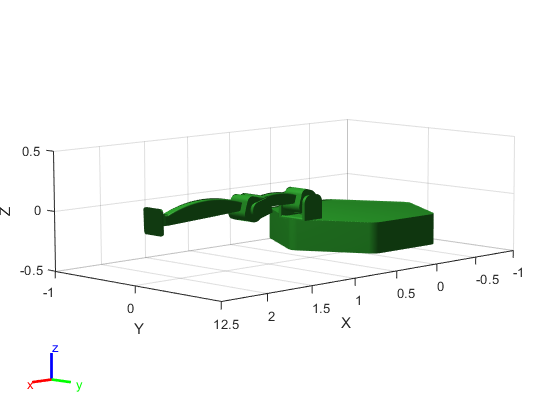

body_mesh = "..\Robot CAD\STL\Body_Link.STL";
link1_vmesh = "..\Robot CAD\STL\Link_One_L2Out.STL";
link2_vmesh = "..\Robot CAD\STL\Link_Two_640_L3Out.STL";
link3_vmesh = "..\Robot CAD\STL\Link_Three_960_EEOut.STL";

link1_cmesh1 = "..\Robot CAD\STL\Collision\Link_One_Part1.STL";
link1_cmesh2 = "..\Robot CAD\STL\Collision\Link_One_Part2.STL";
link1_cmesh3 = "..\Robot CAD\STL\Collision\Link_One_Part3.STL";

link2_cmesh1 = "..\Robot CAD\STL\Collision\Link_Two_Part1.STL";
link2_cmesh2 = "..\Robot CAD\STL\Collision\Link_Two_Part2.STL";
link2_cmesh3 = "..\Robot CAD\STL\Collision\Link_Two_Part3.STL";
link2_cmesh4 = "..\Robot CAD\STL\Collision\Link_Two_Part4.STL";
link2_cmesh5 = "..\Robot CAD\STL\Collision\Link_Two_Part5.STL";

link3_cmesh1 = "..\Robot CAD\STL\Collision\Link_Three_Part1.STL";
link3_cmesh2 = "..\Robot CAD\STL\Collision\Link_Three_Part2.STL";
link3_cmesh3 = "..\Robot CAD\STL\Collision\Link_Three_Part3.STL";
link3_cmesh4 = "..\Robot CAD\STL\Collision\Link_Three_Part4.STL";
link3_cmesh5 = "..\Robot CAD\STL\Collision\Link_Three_Part5.STL";

count = 6; % Counting variable for itterating through the legs with the order being 2, 1, 3, 5, 6, 4 for leg names.

a = [0.625 0 0.640 0.960]; % Link lengths as a 1:1.5 leg ratio.
alpha = [0 pi/2 0 -pi/2];
d = [0 0 0 0];
theta = [pi/3*count 0 0 0];
DHparams = [a(1)      alpha(1)      d(1)   theta(1);
            a(2)      alpha(2)      d(2)   theta(2);
            a(3)      alpha(3)      d(3)   theta(3);
            a(4)      alpha(4)      d(4)   theta(4)];

%Building The Robot by creating a rigid body tree
full_robot = robotics.RigidBodyTree; %Sets rigid body tree to be called robot for callback use

% Define the bodies and their joints
leg_4 = robotics.RigidBody('leg_4'); %Create Leg 6 Origin of the robot.
leg4_jnt1 = robotics.Joint('leg4_jnt1','fixed'); %Create a fixed joint.
leg4_link1 = robotics.RigidBody('leg4_link1'); %Create Link 1 of the leg 6.
leg4_jnt2 = robotics.Joint('leg4_jnt2','revolute'); %Create a revolute joint.
leg4_link2 = robotics.RigidBody('leg4_link2'); %Create Link 2 of the leg 6.
leg4_jnt3 = robotics.Joint('leg4_jnt3','revolute'); %Create a revolute joint.
leg4_link3 = robotics.RigidBody('leg4_link3'); %Create Link 3 of the leg 6.
leg4_jnt4 = robotics.Joint('leg4_jnt4','revolute'); %Create a revolute joint.

% Specify the body-to-body transformation using DH parameters
setFixedTransform(leg4_jnt1,DHparams(1,:),'dh');
setFixedTransform(leg4_jnt2,DHparams(2,:),'dh');
setFixedTransform(leg4_jnt3,DHparams(3,:),'dh');
setFixedTransform(leg4_jnt4,DHparams(4,:),'dh');

% Specify the body joints

leg_4.Joint = leg4_jnt1;
leg4_link1.Joint = leg4_jnt2;
leg4_link2.Joint = leg4_jnt3;
leg4_link3.Joint = leg4_jnt4;

% Add the STL visual to the body
addVisual(leg_4, "Mesh", body_mesh);

% Add the STL visual to the first links
addVisual(leg4_link1, "Mesh", link1_vmesh);

% Add the STL visual to the second links
addVisual(leg4_link2, "Mesh", link2_vmesh);

% Add the STL visual to the third links
addVisual(leg4_link3, "Mesh", link3_vmesh);

% Add the STL collisions to the body (shows as full hull of STL geometry)
addCollision(leg_4, "mesh", body_mesh);

% Add the STL collisions to the first link (shows as full hull of STL geometry)
addCollision(leg4_link1, "mesh", link1_cmesh1);
addCollision(leg4_link1, "mesh", link1_cmesh2);
addCollision(leg4_link1, "mesh", link1_cmesh3);

% Add the STL collisions to the second link (shows as full hull of STL geometry)
addCollision(leg4_link2, "mesh", link2_cmesh1);
addCollision(leg4_link2, "mesh", link2_cmesh2);
addCollision(leg4_link2, "mesh", link2_cmesh3);
addCollision(leg4_link2, "mesh", link2_cmesh4);
addCollision(leg4_link2, "mesh", link2_cmesh5);

% Add the STL collisions to the third link (shows as full hull of STL geometry)
addCollision(leg4_link3, "mesh", link3_cmesh1);
addCollision(leg4_link3, "mesh", link3_cmesh2);
addCollision(leg4_link3, "mesh", link3_cmesh3);
addCollision(leg4_link3, "mesh", link3_cmesh4);
addCollision(leg4_link3, "mesh", link3_cmesh5);

% Attach the sixth Leg
addBody(full_robot,leg_4,'base')
addBody(full_robot,leg4_link1,'leg_4');
addBody(full_robot,leg4_link2,'leg4_link1');
addBody(full_robot,leg4_link3,'leg4_link2');

config = homeConfiguration(full_robot);

% figure;
% show(full_robot,config,'Collisions','off','Visuals','on');

print_figures = true;

figure;
show(full_robot,config,'Collisions','on','Visuals','off',"Frames","off");
xlim([-1 2.5])
ylim([-1 1])
zlim([-0.5, 0.5])
if print_figures
    set(gcf,'Units','inches'); % Set the units of the figure
    screenposition = get(gcf,'Position'); % Measure the size of the figure
    set(gcf,'PaperPosition', [0 0 screenposition(3:4)],'PaperSize' , (screenposition(3:4))); % Configures the print paper size to fit the figure size
    print('Robot Leg Collision Mesh', '-dpng', '-r600') % Save figure as PNG
end

### Calcualting the Collisions

Due to the design of the robot, we know that we are only concerned about the extereme cases of joint angles and as such, have limited the collision checking to $\pm 10$ degrees away from the maximum positive and negative joint angles. Based on timing of this code, just checking all of those conditions means 10,648 collision checks. With each check taking about 1.45 seconds, this code takes ~4+ hours to run on my computer.

The output variables have been saved as external MATLAB variables that we can read in so now we can double check the 22 out of the 10,648 values that came back as collisions. We can also add an if statement before all of this code so it does not run every time.

run_collision_checks = false;

full_robot.DataFormat = 'row';

if run_collision_checks % Will not run unless "run_collision_checks" is true
    for hip_alpha=1:size(collision_map,1)
        for knee_beta=1:size(collision_map,2)
            for ankle_gama=1:size(collision_map,3)
                %tic
                counter = counter + 1
                config = [hip_joint_range_r(hip_alpha) knee_joint_range_r(knee_beta) ankle_joint_range_r(ankle_gama)];
                is_self_colliding_parent = checkCollision(full_robot,config,SkippedSelfCollisions="parent");
                if is_self_colliding_parent
                    collision_map(hip_alpha,knee_beta,ankle_gama) = 1;
                    collision_angles(hip_alpha*knee_beta*ankle_gama,:) = config
                    %disp("hit parent at (" + hip_alpha + ", " + knee_beta + ", " + ankle_gama + ")")
                else
                    % Pass and do nothing
                end
                %toc The average time was 1.45 seconds to calculate
            end
        end
    end
    
    %save("Collision_Map.mat","collision_map")
    %save("Collision_Angles.mat","collision_angles")
end

calcualte_double_check = false;

if calcualte_double_check
    load("Collision_Angles.mat");
    
    for double_check=1:22
        figure;
        show(full_robot,collision_angles(double_check,:),'Collisions','on','Visuals','off');
    end
    figure;
    middle = collision_angles(double_check,:);
    middle(1) = 0;
    middle(3) = deg2rad(-134);
    show(full_robot,middle,'Collisions','on','Visuals','off');
end

From this model, we can determine that our final joint angles are $\pm 45$ for the hip, $-38$ to $102$ for the knee, and $-134$ to $0$ for the ankle with the single condition that all the legs cannot be at full negative of both joint 2 and joint 3 at the same time or the foot will collide.

plot_max_video = flase;

if plot_max_video
   hip_left = linspace(-45,45,91)';
   hip_right = flip(hip_left);
   knee_down = linspace(102,-38,141)';
   knee_up = flip(knee_down);
   ankle_down = linspace(0,-134,135)';
   ankle_up = flip(ankle_down);

   % Starting from full right, full up, rotating ankle down and then knee
   % down and then hip left, knee up, ankle up
   % ankle_down = 135
   % knee_down = 141
   % hip_left = 91
   % knee_up = 141
   % ankle_up = 135
   % hip_right = 91
   % ----------------
   % config = (135+141+91+141+135+91=734, 3)
   config = zeros(734,3);
   config(1:135,1) = -45;
   config(1:135,2) = 102;
   config(1:135,3) = ankle_down; % 135 values

   config(136:276,1) = -45;
   config(136:276,2) = knee_down; % 141 values
   config(136:276,3) = -134;

   config(277:367,1) = hip_left; % 91 values
   config(277:367,2) = -38;
   config(277:367,3) = -134;

   config(368:508,1) = 45;
   config(368:508,2) = knee_up; % 141 values
   config(368:508,3) = -134;

   config(509:643,1) = 45;
   config(509:643,2) = 102;
   config(509:643,3) = ankle_up; % 135 values

   config(644:734,1) = hip_right;  % 91 values
   config(644:734,2) = 102;
   config(644:734,3) = 0;

   config = deg2rad(config);
   
   figure('Name','Hexapod Robot Single Leg Maximum Joint Angles Animated','units','normalized','outerposition',[0 0 1 1]);
   show(full_robot,config(1,:),"Frames","off");

   dim = [.3 .55 .4 .3];
   str = {'Joint 1 [deg]: ' + string(rad2deg(config(1,1))),'Joint 2 [deg]: ' + string(rad2deg(config(1,2))), 'Joint 3 [deg]: ' + string(rad2deg(config(1,3)))};
   annotation('textbox',dim,'String',str,'FitBoxToText','on');
   
   G(1) = getframe(gcf); %creates frame of each incremental movement
   for i=2:size(config,1)
     show(full_robot,config(i,:),"Frames","off","PreservePlot",false,"FastUpdate",true);
     
     delete(findall(gcf,'type','annotation'));
     dim = [.3 .55 .4 .3];
     str = {'Joint 1 [deg]: ' + string(rad2deg(config(i,1))),'Joint 2 [deg]: ' + string(rad2deg(config(i,2))), 'Joint 3 [deg]: ' + string(rad2deg(config(i,3)))};
     annotation('textbox',dim,'String',str,'FitBoxToText','on');
     drawnow;

     G(i) = getframe(gcf); %creates frame of each incremental movement
   end
   drawnow;
   % Create video of animation
   % commented out to not generate video every time the code runs
   % Create video of animation
   movie(G);
   % create the video writer
   writerObj = VideoWriter('Hexapod Robot Single Leg Maximum Joint Angles - Fast - HD');
   writerObj.FrameRate = 20;
   % set the seconds per image
   % open the video writer
   open(writerObj);
   % write the frames to the video
   for i=1:length(G)
      % convert the image to a frame
      frame = G(i);
      writeVideo(writerObj, frame);
   end
   % close the writer object
   close(writerObj);
end